% ASEN 5044 HWK #3 
% Problem 1

dt = 0.05 % sampling interval

dt = 0.0500

tlist = 0:dt:5; % time sample matrix
A =[ 0,1,0,0;-2,0,1,0;0,0,0,1;1,0,-2,0];
B = [0,0;-1,0;0,0;1,1];
C = [1,0,0,0;0,1,0,-1];
D = zeros(2);

Ctilde = zeros(2,4); % zero matrix to compute DT model
Atilde = [A,B;Ctilde,D]; % compiled matrix
FG=expm(Atilde*dt); % DT conversion
F = FG(1:4,1:4);
G = FG(1:4,5:6);

% since A is invertible, can use 
% G = F*(eye(4)-expm(-A*dt))*inv(A)*B
% which gives same values for G so not necessary

H = C;
M = D;

lambda = eig(A);
lambda_norm = abs(lambda);

% build arrays of data by interleaving columns
output = importdata("hw3problem1data.mat");
ydata = output.Ydata;
udata = output.Udata;
n = 100; % number of samples
y = []; u = [];
for i = 1:n
    y = [y; ydata(i,:)'];
    u = [u; udata(i,:)'];
end

% build F matrix [F,FF,...] for x0
FF = [];
for i = 1 : 100
    FF = [FF;F^(i)];
end

% build observability matrix [HF,HFF,...]
O = [];
for i = 1 : 100
    O = [O;H*F^(i);]
end

O =     0.9975    0.0500    0.0012    0.0000
   -0.1498    0.9963    0.1498   -0.9963


O =     0.9975    0.0500    0.0012    0.0000
   -0.1498    0.9963    0.1498   -0.9963
    0.9900    0.0997    0.0050    0.0002
   -0.2985    0.9850    0.2985   -0.9850


O =     0.9975    0.0500    0.0012    0.0000
   -0.1498    0.9963    0.1498   -0.9963
    0.9900    0.0997    0.0050    0.0002
   -0.2985    0.9850    0.2985   -0.9850
    0.9776    0.1489    0.0112    0.0006
   -0.4450    0.9664    0.4450   -0.9664


O =     0.9975    0.0500    0.0012    0.0000
   -0.1498    0.9963    0.1498   -0.9963
    0.9900    0.0997    0.0050    0.0002
   -0.2985    0.9850    0.2985   -0.9850
    0.9776    0.1489    0.0112    0.0006
   -0.4450    0.9664    0.4450   -0.9664
    0.9603    0.1973    0.0197    0.0013
   -0.5881    0.9406    0.5881   -0.9406


O =     0.9975    0.0500    0.0012    0.0000
   -0.1498    0.9963    0.1498   -0.9963
    0.9900    0.0997    0.0050    0.0002
   -0.2985    0.9850    0.2985   -0.9850
    0.9776    0.1489    0.0112    0.0006
   -0.4450    0.9664    0.4450   -0.9664
    0.9603    0.1973    0.0197    0.0013
   -0.5881    0.9406    0.5881   -0.9406
    0.9383    0.2448    0.0306    0.0026
   -0.7268    0.9077    0.7268   -0.9077


O =     0.9975    0.0500    0.0012    0.0000
   -0.1498    0.9963    0.1498   -0.9963
    0.9900    0.0997    0.0050    0.0002
   -0.2985    0.9850    0.2985   -0.9850
    0.9776    0.1489    0.0112    0.0006
   -0.4450    0.9664    0.4450   -0.9664
    0.9603    0.1973    0.0197    0.0013
   -0.5881    0.9406    0.5881   -0.9406
    0.9383    0.2448    0.0306    0.0026
   -0.7268    0.9077    0.7268   -0.9077


O =     0.9975    0.0500    0.0012    0.0000
   -0.1498    0.9963    0.1498   -0.9963
    0.9900    0.0997    0.0050    0.0002
   -0.2985    0.9850    0.2985   -0.9850
    0.9776    0.1489    0.0112    0.0006
   -0.4450    0.9664    0.4450   -0.9664
    0.9603    0.1973    0.0197    0.0013
   -0.5881    0.9406    0.5881   -0.9406
    0.9383    0.2448    0.0306    0.0026
   -0.7268    0.9077    0.7268   -0.9077


O =     0.9975    0.0500    0.0012    0.0000
   -0.1498    0.9963    0.1498   -0.9963
    0.9900    0.0997    0.0050    0.0002
   -0.2985    0.9850    0.2985   -0.9850
    0.9776    0.1489    0.0112    0.0006
   -0.4450    0.9664    0.4450   -0.9664
    0.9603    0.1973    0.0197    0.0013
   -0.5881    0.9406    0.5881   -0.9406
    0.9383    0.2448    0.0306    0.0026
   -0.7268    0.9077    0.7268   -0.9077


O =     0.9975    0.0500    0.0012    0.0000
   -0.1498    0.9963    0.1498   -0.9963
    0.9900    0.0997    0.0050    0.0002
   -0.2985    0.9850    0.2985   -0.9850
    0.9776    0.1489    0.0112    0.0006
   -0.4450    0.9664    0.4450   -0.9664
    0.9603    0.1973    0.0197    0.0013
   -0.5881    0.9406    0.5881   -0.9406
    0.9383    0.2448    0.0306    0.0026
   -0.7268    0.9077    0.7268   -0.9077


O =     0.9975    0.0500    0.0012    0.0000
   -0.1498    0.9963    0.1498   -0.9963
    0.9900    0.0997    0.0050    0.0002
   -0.2985    0.9850    0.2985   -0.9850
    0.9776    0.1489    0.0112    0.0006
   -0.4450    0.9664    0.4450   -0.9664
    0.9603    0.1973    0.0197    0.0013
   -0.5881    0.9406    0.5881   -0.9406
    0.9383    0.2448    0.0306    0.0026
   -0.7268    0.9077    0.7268   -0.9077


O =     0.9975    0.0500    0.0012    0.0000
   -0.1498    0.9963    0.1498   -0.9963
    0.9900    0.0997    0.0050    0.0002
   -0.2985    0.9850    0.2985   -0.9850
    0.9776    0.1489    0.0112    0.0006
   -0.4450    0.9664    0.4450   -0.9664
    0.9603    0.1973    0.0197    0.0013
   -0.5881    0.9406    0.5881   -0.9406
    0.9383    0.2448    0.0306    0.0026
   -0.7268    0.9077    0.7268   -0.9077


O =     0.9975    0.0500    0.0012    0.0000
   -0.1498    0.9963    0.1498   -0.9963
    0.9900    0.0997    0.0050    0.0002
   -0.2985    0.9850    0.2985   -0.9850
    0.9776    0.1489    0.0112    0.0006
   -0.4450    0.9664    0.4450   -0.9664
    0.9603    0.1973    0.0197    0.0013
   -0.5881    0.9406    0.5881   -0.9406
    0.9383    0.2448    0.0306    0.0026
   -0.7268    0.9077    0.7268   -0.9077


O =     0.9975    0.0500    0.0012    0.0000
   -0.1498    0.9963    0.1498   -0.9963
    0.9900    0.0997    0.0050    0.0002
   -0.2985    0.9850    0.2985   -0.9850
    0.9776    0.1489    0.0112    0.0006
   -0.4450    0.9664    0.4450   -0.9664
    0.9603    0.1973    0.0197    0.0013
   -0.5881    0.9406    0.5881   -0.9406
    0.9383    0.2448    0.0306    0.0026
   -0.7268    0.9077    0.7268   -0.9077


O =     0.9975    0.0500    0.0012    0.0000
   -0.1498    0.9963    0.1498   -0.9963
    0.9900    0.0997    0.0050    0.0002
   -0.2985    0.9850    0.2985   -0.9850
    0.9776    0.1489    0.0112    0.0006
   -0.4450    0.9664    0.4450   -0.9664
    0.9603    0.1973    0.0197    0.0013
   -0.5881    0.9406    0.5881   -0.9406
    0.9383    0.2448    0.0306    0.0026
   -0.7268    0.9077    0.7268   -0.9077


O =     0.9975    0.0500    0.0012    0.0000
   -0.1498    0.9963    0.1498   -0.9963
    0.9900    0.0997    0.0050    0.0002
   -0.2985    0.9850    0.2985   -0.9850
    0.9776    0.1489    0.0112    0.0006
   -0.4450    0.9664    0.4450   -0.9664
    0.9603    0.1973    0.0197    0.0013
   -0.5881    0.9406    0.5881   -0.9406
    0.9383    0.2448    0.0306    0.0026
   -0.7268    0.9077    0.7268   -0.9077


O =     0.9975    0.0500    0.0012    0.0000
   -0.1498    0.9963    0.1498   -0.9963
    0.9900    0.0997    0.0050    0.0002
   -0.2985    0.9850    0.2985   -0.9850
    0.9776    0.1489    0.0112    0.0006
   -0.4450    0.9664    0.4450   -0.9664
    0.9603    0.1973    0.0197    0.0013
   -0.5881    0.9406    0.5881   -0.9406
    0.9383    0.2448    0.0306    0.0026
   -0.7268    0.9077    0.7268   -0.9077


O =     0.9975    0.0500    0.0012    0.0000
   -0.1498    0.9963    0.1498   -0.9963
    0.9900    0.0997    0.0050    0.0002
   -0.2985    0.9850    0.2985   -0.9850
    0.9776    0.1489    0.0112    0.0006
   -0.4450    0.9664    0.4450   -0.9664
    0.9603    0.1973    0.0197    0.0013
   -0.5881    0.9406    0.5881   -0.9406
    0.9383    0.2448    0.0306    0.0026
   -0.7268    0.9077    0.7268   -0.9077


O =     0.9975    0.0500    0.0012    0.0000
   -0.1498    0.9963    0.1498   -0.9963
    0.9900    0.0997    0.0050    0.0002
   -0.2985    0.9850    0.2985   -0.9850
    0.9776    0.1489    0.0112    0.0006
   -0.4450    0.9664    0.4450   -0.9664
    0.9603    0.1973    0.0197    0.0013
   -0.5881    0.9406    0.5881   -0.9406
    0.9383    0.2448    0.0306    0.0026
   -0.7268    0.9077    0.7268   -0.9077


O =     0.9975    0.0500    0.0012    0.0000
   -0.1498    0.9963    0.1498   -0.9963
    0.9900    0.0997    0.0050    0.0002
   -0.2985    0.9850    0.2985   -0.9850
    0.9776    0.1489    0.0112    0.0006
   -0.4450    0.9664    0.4450   -0.9664
    0.9603    0.1973    0.0197    0.0013
   -0.5881    0.9406    0.5881   -0.9406
    0.9383    0.2448    0.0306    0.0026
   -0.7268    0.9077    0.7268   -0.9077


O =     0.9975    0.0500    0.0012    0.0000
   -0.1498    0.9963    0.1498   -0.9963
    0.9900    0.0997    0.0050    0.0002
   -0.2985    0.9850    0.2985   -0.9850
    0.9776    0.1489    0.0112    0.0006
   -0.4450    0.9664    0.4450   -0.9664
    0.9603    0.1973    0.0197    0.0013
   -0.5881    0.9406    0.5881   -0.9406
    0.9383    0.2448    0.0306    0.0026
   -0.7268    0.9077    0.7268   -0.9077


O =     0.9975    0.0500    0.0012    0.0000
   -0.1498    0.9963    0.1498   -0.9963
    0.9900    0.0997    0.0050    0.0002
   -0.2985    0.9850    0.2985   -0.9850
    0.9776    0.1489    0.0112    0.0006
   -0.4450    0.9664    0.4450   -0.9664
    0.9603    0.1973    0.0197    0.0013
   -0.5881    0.9406    0.5881   -0.9406
    0.9383    0.2448    0.0306    0.0026
   -0.7268    0.9077    0.7268   -0.9077


O =     0.9975    0.0500    0.0012    0.0000
   -0.1498    0.9963    0.1498   -0.9963
    0.9900    0.0997    0.0050    0.0002
   -0.2985    0.9850    0.2985   -0.9850
    0.9776    0.1489    0.0112    0.0006
   -0.4450    0.9664    0.4450   -0.9664
    0.9603    0.1973    0.0197    0.0013
   -0.5881    0.9406    0.5881   -0.9406
    0.9383    0.2448    0.0306    0.0026
   -0.7268    0.9077    0.7268   -0.9077


O =     0.9975    0.0500    0.0012    0.0000
   -0.1498    0.9963    0.1498   -0.9963
    0.9900    0.0997    0.0050    0.0002
   -0.2985    0.9850    0.2985   -0.9850
    0.9776    0.1489    0.0112    0.0006
   -0.4450    0.9664    0.4450   -0.9664
    0.9603    0.1973    0.0197    0.0013
   -0.5881    0.9406    0.5881   -0.9406
    0.9383    0.2448    0.0306    0.0026
   -0.7268    0.9077    0.7268   -0.9077


O =     0.9975    0.0500    0.0012    0.0000
   -0.1498    0.9963    0.1498   -0.9963
    0.9900    0.0997    0.0050    0.0002
   -0.2985    0.9850    0.2985   -0.9850
    0.9776    0.1489    0.0112    0.0006
   -0.4450    0.9664    0.4450   -0.9664
    0.9603    0.1973    0.0197    0.0013
   -0.5881    0.9406    0.5881   -0.9406
    0.9383    0.2448    0.0306    0.0026
   -0.7268    0.9077    0.7268   -0.9077


O =     0.9975    0.0500    0.0012    0.0000
   -0.1498    0.9963    0.1498   -0.9963
    0.9900    0.0997    0.0050    0.0002
   -0.2985    0.9850    0.2985   -0.9850
    0.9776    0.1489    0.0112    0.0006
   -0.4450    0.9664    0.4450   -0.9664
    0.9603    0.1973    0.0197    0.0013
   -0.5881    0.9406    0.5881   -0.9406
    0.9383    0.2448    0.0306    0.0026
   -0.7268    0.9077    0.7268   -0.9077


O =     0.9975    0.0500    0.0012    0.0000
   -0.1498    0.9963    0.1498   -0.9963
    0.9900    0.0997    0.0050    0.0002
   -0.2985    0.9850    0.2985   -0.9850
    0.9776    0.1489    0.0112    0.0006
   -0.4450    0.9664    0.4450   -0.9664
    0.9603    0.1973    0.0197    0.0013
   -0.5881    0.9406    0.5881   -0.9406
    0.9383    0.2448    0.0306    0.0026
   -0.7268    0.9077    0.7268   -0.9077


O =     0.9975    0.0500    0.0012    0.0000
   -0.1498    0.9963    0.1498   -0.9963
    0.9900    0.0997    0.0050    0.0002
   -0.2985    0.9850    0.2985   -0.9850
    0.9776    0.1489    0.0112    0.0006
   -0.4450    0.9664    0.4450   -0.9664
    0.9603    0.1973    0.0197    0.0013
   -0.5881    0.9406    0.5881   -0.9406
    0.9383    0.2448    0.0306    0.0026
   -0.7268    0.9077    0.7268   -0.9077


O =     0.9975    0.0500    0.0012    0.0000
   -0.1498    0.9963    0.1498   -0.9963
    0.9900    0.0997    0.0050    0.0002
   -0.2985    0.9850    0.2985   -0.9850
    0.9776    0.1489    0.0112    0.0006
   -0.4450    0.9664    0.4450   -0.9664
    0.9603    0.1973    0.0197    0.0013
   -0.5881    0.9406    0.5881   -0.9406
    0.9383    0.2448    0.0306    0.0026
   -0.7268    0.9077    0.7268   -0.9077


O =     0.9975    0.0500    0.0012    0.0000
   -0.1498    0.9963    0.1498   -0.9963
    0.9900    0.0997    0.0050    0.0002
   -0.2985    0.9850    0.2985   -0.9850
    0.9776    0.1489    0.0112    0.0006
   -0.4450    0.9664    0.4450   -0.9664
    0.9603    0.1973    0.0197    0.0013
   -0.5881    0.9406    0.5881   -0.9406
    0.9383    0.2448    0.0306    0.0026
   -0.7268    0.9077    0.7268   -0.9077


O =     0.9975    0.0500    0.0012    0.0000
   -0.1498    0.9963    0.1498   -0.9963
    0.9900    0.0997    0.0050    0.0002
   -0.2985    0.9850    0.2985   -0.9850
    0.9776    0.1489    0.0112    0.0006
   -0.4450    0.9664    0.4450   -0.9664
    0.9603    0.1973    0.0197    0.0013
   -0.5881    0.9406    0.5881   -0.9406
    0.9383    0.2448    0.0306    0.0026
   -0.7268    0.9077    0.7268   -0.9077


O =     0.9975    0.0500    0.0012    0.0000
   -0.1498    0.9963    0.1498   -0.9963
    0.9900    0.0997    0.0050    0.0002
   -0.2985    0.9850    0.2985   -0.9850
    0.9776    0.1489    0.0112    0.0006
   -0.4450    0.9664    0.4450   -0.9664
    0.9603    0.1973    0.0197    0.0013
   -0.5881    0.9406    0.5881   -0.9406
    0.9383    0.2448    0.0306    0.0026
   -0.7268    0.9077    0.7268   -0.9077


O =     0.9975    0.0500    0.0012    0.0000
   -0.1498    0.9963    0.1498   -0.9963
    0.9900    0.0997    0.0050    0.0002
   -0.2985    0.9850    0.2985   -0.9850
    0.9776    0.1489    0.0112    0.0006
   -0.4450    0.9664    0.4450   -0.9664
    0.9603    0.1973    0.0197    0.0013
   -0.5881    0.9406    0.5881   -0.9406
    0.9383    0.2448    0.0306    0.0026
   -0.7268    0.9077    0.7268   -0.9077


O =     0.9975    0.0500    0.0012    0.0000
   -0.1498    0.9963    0.1498   -0.9963
    0.9900    0.0997    0.0050    0.0002
   -0.2985    0.9850    0.2985   -0.9850
    0.9776    0.1489    0.0112    0.0006
   -0.4450    0.9664    0.4450   -0.9664
    0.9603    0.1973    0.0197    0.0013
   -0.5881    0.9406    0.5881   -0.9406
    0.9383    0.2448    0.0306    0.0026
   -0.7268    0.9077    0.7268   -0.9077


O =     0.9975    0.0500    0.0012    0.0000
   -0.1498    0.9963    0.1498   -0.9963
    0.9900    0.0997    0.0050    0.0002
   -0.2985    0.9850    0.2985   -0.9850
    0.9776    0.1489    0.0112    0.0006
   -0.4450    0.9664    0.4450   -0.9664
    0.9603    0.1973    0.0197    0.0013
   -0.5881    0.9406    0.5881   -0.9406
    0.9383    0.2448    0.0306    0.0026
   -0.7268    0.9077    0.7268   -0.9077


O =     0.9975    0.0500    0.0012    0.0000
   -0.1498    0.9963    0.1498   -0.9963
    0.9900    0.0997    0.0050    0.0002
   -0.2985    0.9850    0.2985   -0.9850
    0.9776    0.1489    0.0112    0.0006
   -0.4450    0.9664    0.4450   -0.9664
    0.9603    0.1973    0.0197    0.0013
   -0.5881    0.9406    0.5881   -0.9406
    0.9383    0.2448    0.0306    0.0026
   -0.7268    0.9077    0.7268   -0.9077


O =     0.9975    0.0500    0.0012    0.0000
   -0.1498    0.9963    0.1498   -0.9963
    0.9900    0.0997    0.0050    0.0002
   -0.2985    0.9850    0.2985   -0.9850
    0.9776    0.1489    0.0112    0.0006
   -0.4450    0.9664    0.4450   -0.9664
    0.9603    0.1973    0.0197    0.0013
   -0.5881    0.9406    0.5881   -0.9406
    0.9383    0.2448    0.0306    0.0026
   -0.7268    0.9077    0.7268   -0.9077


O =     0.9975    0.0500    0.0012    0.0000
   -0.1498    0.9963    0.1498   -0.9963
    0.9900    0.0997    0.0050    0.0002
   -0.2985    0.9850    0.2985   -0.9850
    0.9776    0.1489    0.0112    0.0006
   -0.4450    0.9664    0.4450   -0.9664
    0.9603    0.1973    0.0197    0.0013
   -0.5881    0.9406    0.5881   -0.9406
    0.9383    0.2448    0.0306    0.0026
   -0.7268    0.9077    0.7268   -0.9077


O =     0.9975    0.0500    0.0012    0.0000
   -0.1498    0.9963    0.1498   -0.9963
    0.9900    0.0997    0.0050    0.0002
   -0.2985    0.9850    0.2985   -0.9850
    0.9776    0.1489    0.0112    0.0006
   -0.4450    0.9664    0.4450   -0.9664
    0.9603    0.1973    0.0197    0.0013
   -0.5881    0.9406    0.5881   -0.9406
    0.9383    0.2448    0.0306    0.0026
   -0.7268    0.9077    0.7268   -0.9077


O =     0.9975    0.0500    0.0012    0.0000
   -0.1498    0.9963    0.1498   -0.9963
    0.9900    0.0997    0.0050    0.0002
   -0.2985    0.9850    0.2985   -0.9850
    0.9776    0.1489    0.0112    0.0006
   -0.4450    0.9664    0.4450   -0.9664
    0.9603    0.1973    0.0197    0.0013
   -0.5881    0.9406    0.5881   -0.9406
    0.9383    0.2448    0.0306    0.0026
   -0.7268    0.9077    0.7268   -0.9077


O =     0.9975    0.0500    0.0012    0.0000
   -0.1498    0.9963    0.1498   -0.9963
    0.9900    0.0997    0.0050    0.0002
   -0.2985    0.9850    0.2985   -0.9850
    0.9776    0.1489    0.0112    0.0006
   -0.4450    0.9664    0.4450   -0.9664
    0.9603    0.1973    0.0197    0.0013
   -0.5881    0.9406    0.5881   -0.9406
    0.9383    0.2448    0.0306    0.0026
   -0.7268    0.9077    0.7268   -0.9077


O =     0.9975    0.0500    0.0012    0.0000
   -0.1498    0.9963    0.1498   -0.9963
    0.9900    0.0997    0.0050    0.0002
   -0.2985    0.9850    0.2985   -0.9850
    0.9776    0.1489    0.0112    0.0006
   -0.4450    0.9664    0.4450   -0.9664
    0.9603    0.1973    0.0197    0.0013
   -0.5881    0.9406    0.5881   -0.9406
    0.9383    0.2448    0.0306    0.0026
   -0.7268    0.9077    0.7268   -0.9077


O =     0.9975    0.0500    0.0012    0.0000
   -0.1498    0.9963    0.1498   -0.9963
    0.9900    0.0997    0.0050    0.0002
   -0.2985    0.9850    0.2985   -0.9850
    0.9776    0.1489    0.0112    0.0006
   -0.4450    0.9664    0.4450   -0.9664
    0.9603    0.1973    0.0197    0.0013
   -0.5881    0.9406    0.5881   -0.9406
    0.9383    0.2448    0.0306    0.0026
   -0.7268    0.9077    0.7268   -0.9077


O =     0.9975    0.0500    0.0012    0.0000
   -0.1498    0.9963    0.1498   -0.9963
    0.9900    0.0997    0.0050    0.0002
   -0.2985    0.9850    0.2985   -0.9850
    0.9776    0.1489    0.0112    0.0006
   -0.4450    0.9664    0.4450   -0.9664
    0.9603    0.1973    0.0197    0.0013
   -0.5881    0.9406    0.5881   -0.9406
    0.9383    0.2448    0.0306    0.0026
   -0.7268    0.9077    0.7268   -0.9077


O =     0.9975    0.0500    0.0012    0.0000
   -0.1498    0.9963    0.1498   -0.9963
    0.9900    0.0997    0.0050    0.0002
   -0.2985    0.9850    0.2985   -0.9850
    0.9776    0.1489    0.0112    0.0006
   -0.4450    0.9664    0.4450   -0.9664
    0.9603    0.1973    0.0197    0.0013
   -0.5881    0.9406    0.5881   -0.9406
    0.9383    0.2448    0.0306    0.0026
   -0.7268    0.9077    0.7268   -0.9077


O =     0.9975    0.0500    0.0012    0.0000
   -0.1498    0.9963    0.1498   -0.9963
    0.9900    0.0997    0.0050    0.0002
   -0.2985    0.9850    0.2985   -0.9850
    0.9776    0.1489    0.0112    0.0006
   -0.4450    0.9664    0.4450   -0.9664
    0.9603    0.1973    0.0197    0.0013
   -0.5881    0.9406    0.5881   -0.9406
    0.9383    0.2448    0.0306    0.0026
   -0.7268    0.9077    0.7268   -0.9077


O =     0.9975    0.0500    0.0012    0.0000
   -0.1498    0.9963    0.1498   -0.9963
    0.9900    0.0997    0.0050    0.0002
   -0.2985    0.9850    0.2985   -0.9850
    0.9776    0.1489    0.0112    0.0006
   -0.4450    0.9664    0.4450   -0.9664
    0.9603    0.1973    0.0197    0.0013
   -0.5881    0.9406    0.5881   -0.9406
    0.9383    0.2448    0.0306    0.0026
   -0.7268    0.9077    0.7268   -0.9077


O =     0.9975    0.0500    0.0012    0.0000
   -0.1498    0.9963    0.1498   -0.9963
    0.9900    0.0997    0.0050    0.0002
   -0.2985    0.9850    0.2985   -0.9850
    0.9776    0.1489    0.0112    0.0006
   -0.4450    0.9664    0.4450   -0.9664
    0.9603    0.1973    0.0197    0.0013
   -0.5881    0.9406    0.5881   -0.9406
    0.9383    0.2448    0.0306    0.0026
   -0.7268    0.9077    0.7268   -0.9077


O =     0.9975    0.0500    0.0012    0.0000
   -0.1498    0.9963    0.1498   -0.9963
    0.9900    0.0997    0.0050    0.0002
   -0.2985    0.9850    0.2985   -0.9850
    0.9776    0.1489    0.0112    0.0006
   -0.4450    0.9664    0.4450   -0.9664
    0.9603    0.1973    0.0197    0.0013
   -0.5881    0.9406    0.5881   -0.9406
    0.9383    0.2448    0.0306    0.0026
   -0.7268    0.9077    0.7268   -0.9077


O =     0.9975    0.0500    0.0012    0.0000
   -0.1498    0.9963    0.1498   -0.9963
    0.9900    0.0997    0.0050    0.0002
   -0.2985    0.9850    0.2985   -0.9850
    0.9776    0.1489    0.0112    0.0006
   -0.4450    0.9664    0.4450   -0.9664
    0.9603    0.1973    0.0197    0.0013
   -0.5881    0.9406    0.5881   -0.9406
    0.9383    0.2448    0.0306    0.0026
   -0.7268    0.9077    0.7268   -0.9077


O =     0.9975    0.0500    0.0012    0.0000
   -0.1498    0.9963    0.1498   -0.9963
    0.9900    0.0997    0.0050    0.0002
   -0.2985    0.9850    0.2985   -0.9850
    0.9776    0.1489    0.0112    0.0006
   -0.4450    0.9664    0.4450   -0.9664
    0.9603    0.1973    0.0197    0.0013
   -0.5881    0.9406    0.5881   -0.9406
    0.9383    0.2448    0.0306    0.0026
   -0.7268    0.9077    0.7268   -0.9077


O = 102×4
    0.9975    0.0500    0.0012    0.0000
   -0.1498    0.9963    0.1498   -0.9963
    0.9900    0.0997    0.0050    0.0002
   -0.2985    0.9850    0.2985   -0.9850
    0.9776    0.1489    0.0112    0.0006
   -0.4450    0.9664    0.4450   -0.9664
    0.9603    0.1973    0.0197    0.0013
   -0.5881    0.9406    0.5881   -0.9406
    0.9383    0.2448    0.0306    0.0026
   -0.7268    0.9077    0.7268   -0.9077


O = 104×4
    0.9975    0.0500    0.0012    0.0000
   -0.1498    0.9963    0.1498   -0.9963
    0.9900    0.0997    0.0050    0.0002
   -0.2985    0.9850    0.2985   -0.9850
    0.9776    0.1489    0.0112    0.0006
   -0.4450    0.9664    0.4450   -0.9664
    0.9603    0.1973    0.0197    0.0013
   -0.5881    0.9406    0.5881   -0.9406
    0.9383    0.2448    0.0306    0.0026
   -0.7268    0.9077    0.7268   -0.9077


O = 106×4
    0.9975    0.0500    0.0012    0.0000
   -0.1498    0.9963    0.1498   -0.9963
    0.9900    0.0997    0.0050    0.0002
   -0.2985    0.9850    0.2985   -0.9850
    0.9776    0.1489    0.0112    0.0006
   -0.4450    0.9664    0.4450   -0.9664
    0.9603    0.1973    0.0197    0.0013
   -0.5881    0.9406    0.5881   -0.9406
    0.9383    0.2448    0.0306    0.0026
   -0.7268    0.9077    0.7268   -0.9077


O = 108×4
    0.9975    0.0500    0.0012    0.0000
   -0.1498    0.9963    0.1498   -0.9963
    0.9900    0.0997    0.0050    0.0002
   -0.2985    0.9850    0.2985   -0.9850
    0.9776    0.1489    0.0112    0.0006
   -0.4450    0.9664    0.4450   -0.9664
    0.9603    0.1973    0.0197    0.0013
   -0.5881    0.9406    0.5881   -0.9406
    0.9383    0.2448    0.0306    0.0026
   -0.7268    0.9077    0.7268   -0.9077


O = 110×4
    0.9975    0.0500    0.0012    0.0000
   -0.1498    0.9963    0.1498   -0.9963
    0.9900    0.0997    0.0050    0.0002
   -0.2985    0.9850    0.2985   -0.9850
    0.9776    0.1489    0.0112    0.0006
   -0.4450    0.9664    0.4450   -0.9664
    0.9603    0.1973    0.0197    0.0013
   -0.5881    0.9406    0.5881   -0.9406
    0.9383    0.2448    0.0306    0.0026
   -0.7268    0.9077    0.7268   -0.9077


O = 112×4
    0.9975    0.0500    0.0012    0.0000
   -0.1498    0.9963    0.1498   -0.9963
    0.9900    0.0997    0.0050    0.0002
   -0.2985    0.9850    0.2985   -0.9850
    0.9776    0.1489    0.0112    0.0006
   -0.4450    0.9664    0.4450   -0.9664
    0.9603    0.1973    0.0197    0.0013
   -0.5881    0.9406    0.5881   -0.9406
    0.9383    0.2448    0.0306    0.0026
   -0.7268    0.9077    0.7268   -0.9077


O = 114×4
    0.9975    0.0500    0.0012    0.0000
   -0.1498    0.9963    0.1498   -0.9963
    0.9900    0.0997    0.0050    0.0002
   -0.2985    0.9850    0.2985   -0.9850
    0.9776    0.1489    0.0112    0.0006
   -0.4450    0.9664    0.4450   -0.9664
    0.9603    0.1973    0.0197    0.0013
   -0.5881    0.9406    0.5881   -0.9406
    0.9383    0.2448    0.0306    0.0026
   -0.7268    0.9077    0.7268   -0.9077


O = 116×4
    0.9975    0.0500    0.0012    0.0000
   -0.1498    0.9963    0.1498   -0.9963
    0.9900    0.0997    0.0050    0.0002
   -0.2985    0.9850    0.2985   -0.9850
    0.9776    0.1489    0.0112    0.0006
   -0.4450    0.9664    0.4450   -0.9664
    0.9603    0.1973    0.0197    0.0013
   -0.5881    0.9406    0.5881   -0.9406
    0.9383    0.2448    0.0306    0.0026
   -0.7268    0.9077    0.7268   -0.9077


O = 118×4
    0.9975    0.0500    0.0012    0.0000
   -0.1498    0.9963    0.1498   -0.9963
    0.9900    0.0997    0.0050    0.0002
   -0.2985    0.9850    0.2985   -0.9850
    0.9776    0.1489    0.0112    0.0006
   -0.4450    0.9664    0.4450   -0.9664
    0.9603    0.1973    0.0197    0.0013
   -0.5881    0.9406    0.5881   -0.9406
    0.9383    0.2448    0.0306    0.0026
   -0.7268    0.9077    0.7268   -0.9077


O = 120×4
    0.9975    0.0500    0.0012    0.0000
   -0.1498    0.9963    0.1498   -0.9963
    0.9900    0.0997    0.0050    0.0002
   -0.2985    0.9850    0.2985   -0.9850
    0.9776    0.1489    0.0112    0.0006
   -0.4450    0.9664    0.4450   -0.9664
    0.9603    0.1973    0.0197    0.0013
   -0.5881    0.9406    0.5881   -0.9406
    0.9383    0.2448    0.0306    0.0026
   -0.7268    0.9077    0.7268   -0.9077


O = 122×4
    0.9975    0.0500    0.0012    0.0000
   -0.1498    0.9963    0.1498   -0.9963
    0.9900    0.0997    0.0050    0.0002
   -0.2985    0.9850    0.2985   -0.9850
    0.9776    0.1489    0.0112    0.0006
   -0.4450    0.9664    0.4450   -0.9664
    0.9603    0.1973    0.0197    0.0013
   -0.5881    0.9406    0.5881   -0.9406
    0.9383    0.2448    0.0306    0.0026
   -0.7268    0.9077    0.7268   -0.9077


O = 124×4
    0.9975    0.0500    0.0012    0.0000
   -0.1498    0.9963    0.1498   -0.9963
    0.9900    0.0997    0.0050    0.0002
   -0.2985    0.9850    0.2985   -0.9850
    0.9776    0.1489    0.0112    0.0006
   -0.4450    0.9664    0.4450   -0.9664
    0.9603    0.1973    0.0197    0.0013
   -0.5881    0.9406    0.5881   -0.9406
    0.9383    0.2448    0.0306    0.0026
   -0.7268    0.9077    0.7268   -0.9077


O = 126×4
    0.9975    0.0500    0.0012    0.0000
   -0.1498    0.9963    0.1498   -0.9963
    0.9900    0.0997    0.0050    0.0002
   -0.2985    0.9850    0.2985   -0.9850
    0.9776    0.1489    0.0112    0.0006
   -0.4450    0.9664    0.4450   -0.9664
    0.9603    0.1973    0.0197    0.0013
   -0.5881    0.9406    0.5881   -0.9406
    0.9383    0.2448    0.0306    0.0026
   -0.7268    0.9077    0.7268   -0.9077


O = 128×4
    0.9975    0.0500    0.0012    0.0000
   -0.1498    0.9963    0.1498   -0.9963
    0.9900    0.0997    0.0050    0.0002
   -0.2985    0.9850    0.2985   -0.9850
    0.9776    0.1489    0.0112    0.0006
   -0.4450    0.9664    0.4450   -0.9664
    0.9603    0.1973    0.0197    0.0013
   -0.5881    0.9406    0.5881   -0.9406
    0.9383    0.2448    0.0306    0.0026
   -0.7268    0.9077    0.7268   -0.9077


O = 130×4
    0.9975    0.0500    0.0012    0.0000
   -0.1498    0.9963    0.1498   -0.9963
    0.9900    0.0997    0.0050    0.0002
   -0.2985    0.9850    0.2985   -0.9850
    0.9776    0.1489    0.0112    0.0006
   -0.4450    0.9664    0.4450   -0.9664
    0.9603    0.1973    0.0197    0.0013
   -0.5881    0.9406    0.5881   -0.9406
    0.9383    0.2448    0.0306    0.0026
   -0.7268    0.9077    0.7268   -0.9077


O = 132×4
    0.9975    0.0500    0.0012    0.0000
   -0.1498    0.9963    0.1498   -0.9963
    0.9900    0.0997    0.0050    0.0002
   -0.2985    0.9850    0.2985   -0.9850
    0.9776    0.1489    0.0112    0.0006
   -0.4450    0.9664    0.4450   -0.9664
    0.9603    0.1973    0.0197    0.0013
   -0.5881    0.9406    0.5881   -0.9406
    0.9383    0.2448    0.0306    0.0026
   -0.7268    0.9077    0.7268   -0.9077


O = 134×4
    0.9975    0.0500    0.0012    0.0000
   -0.1498    0.9963    0.1498   -0.9963
    0.9900    0.0997    0.0050    0.0002
   -0.2985    0.9850    0.2985   -0.9850
    0.9776    0.1489    0.0112    0.0006
   -0.4450    0.9664    0.4450   -0.9664
    0.9603    0.1973    0.0197    0.0013
   -0.5881    0.9406    0.5881   -0.9406
    0.9383    0.2448    0.0306    0.0026
   -0.7268    0.9077    0.7268   -0.9077


O = 136×4
    0.9975    0.0500    0.0012    0.0000
   -0.1498    0.9963    0.1498   -0.9963
    0.9900    0.0997    0.0050    0.0002
   -0.2985    0.9850    0.2985   -0.9850
    0.9776    0.1489    0.0112    0.0006
   -0.4450    0.9664    0.4450   -0.9664
    0.9603    0.1973    0.0197    0.0013
   -0.5881    0.9406    0.5881   -0.9406
    0.9383    0.2448    0.0306    0.0026
   -0.7268    0.9077    0.7268   -0.9077


O = 138×4
    0.9975    0.0500    0.0012    0.0000
   -0.1498    0.9963    0.1498   -0.9963
    0.9900    0.0997    0.0050    0.0002
   -0.2985    0.9850    0.2985   -0.9850
    0.9776    0.1489    0.0112    0.0006
   -0.4450    0.9664    0.4450   -0.9664
    0.9603    0.1973    0.0197    0.0013
   -0.5881    0.9406    0.5881   -0.9406
    0.9383    0.2448    0.0306    0.0026
   -0.7268    0.9077    0.7268   -0.9077


O = 140×4
    0.9975    0.0500    0.0012    0.0000
   -0.1498    0.9963    0.1498   -0.9963
    0.9900    0.0997    0.0050    0.0002
   -0.2985    0.9850    0.2985   -0.9850
    0.9776    0.1489    0.0112    0.0006
   -0.4450    0.9664    0.4450   -0.9664
    0.9603    0.1973    0.0197    0.0013
   -0.5881    0.9406    0.5881   -0.9406
    0.9383    0.2448    0.0306    0.0026
   -0.7268    0.9077    0.7268   -0.9077


O = 142×4
    0.9975    0.0500    0.0012    0.0000
   -0.1498    0.9963    0.1498   -0.9963
    0.9900    0.0997    0.0050    0.0002
   -0.2985    0.9850    0.2985   -0.9850
    0.9776    0.1489    0.0112    0.0006
   -0.4450    0.9664    0.4450   -0.9664
    0.9603    0.1973    0.0197    0.0013
   -0.5881    0.9406    0.5881   -0.9406
    0.9383    0.2448    0.0306    0.0026
   -0.7268    0.9077    0.7268   -0.9077


O = 144×4
    0.9975    0.0500    0.0012    0.0000
   -0.1498    0.9963    0.1498   -0.9963
    0.9900    0.0997    0.0050    0.0002
   -0.2985    0.9850    0.2985   -0.9850
    0.9776    0.1489    0.0112    0.0006
   -0.4450    0.9664    0.4450   -0.9664
    0.9603    0.1973    0.0197    0.0013
   -0.5881    0.9406    0.5881   -0.9406
    0.9383    0.2448    0.0306    0.0026
   -0.7268    0.9077    0.7268   -0.9077


O = 146×4
    0.9975    0.0500    0.0012    0.0000
   -0.1498    0.9963    0.1498   -0.9963
    0.9900    0.0997    0.0050    0.0002
   -0.2985    0.9850    0.2985   -0.9850
    0.9776    0.1489    0.0112    0.0006
   -0.4450    0.9664    0.4450   -0.9664
    0.9603    0.1973    0.0197    0.0013
   -0.5881    0.9406    0.5881   -0.9406
    0.9383    0.2448    0.0306    0.0026
   -0.7268    0.9077    0.7268   -0.9077


O = 148×4
    0.9975    0.0500    0.0012    0.0000
   -0.1498    0.9963    0.1498   -0.9963
    0.9900    0.0997    0.0050    0.0002
   -0.2985    0.9850    0.2985   -0.9850
    0.9776    0.1489    0.0112    0.0006
   -0.4450    0.9664    0.4450   -0.9664
    0.9603    0.1973    0.0197    0.0013
   -0.5881    0.9406    0.5881   -0.9406
    0.9383    0.2448    0.0306    0.0026
   -0.7268    0.9077    0.7268   -0.9077


O = 150×4
    0.9975    0.0500    0.0012    0.0000
   -0.1498    0.9963    0.1498   -0.9963
    0.9900    0.0997    0.0050    0.0002
   -0.2985    0.9850    0.2985   -0.9850
    0.9776    0.1489    0.0112    0.0006
   -0.4450    0.9664    0.4450   -0.9664
    0.9603    0.1973    0.0197    0.0013
   -0.5881    0.9406    0.5881   -0.9406
    0.9383    0.2448    0.0306    0.0026
   -0.7268    0.9077    0.7268   -0.9077


O = 152×4
    0.9975    0.0500    0.0012    0.0000
   -0.1498    0.9963    0.1498   -0.9963
    0.9900    0.0997    0.0050    0.0002
   -0.2985    0.9850    0.2985   -0.9850
    0.9776    0.1489    0.0112    0.0006
   -0.4450    0.9664    0.4450   -0.9664
    0.9603    0.1973    0.0197    0.0013
   -0.5881    0.9406    0.5881   -0.9406
    0.9383    0.2448    0.0306    0.0026
   -0.7268    0.9077    0.7268   -0.9077


O = 154×4
    0.9975    0.0500    0.0012    0.0000
   -0.1498    0.9963    0.1498   -0.9963
    0.9900    0.0997    0.0050    0.0002
   -0.2985    0.9850    0.2985   -0.9850
    0.9776    0.1489    0.0112    0.0006
   -0.4450    0.9664    0.4450   -0.9664
    0.9603    0.1973    0.0197    0.0013
   -0.5881    0.9406    0.5881   -0.9406
    0.9383    0.2448    0.0306    0.0026
   -0.7268    0.9077    0.7268   -0.9077


O = 156×4
    0.9975    0.0500    0.0012    0.0000
   -0.1498    0.9963    0.1498   -0.9963
    0.9900    0.0997    0.0050    0.0002
   -0.2985    0.9850    0.2985   -0.9850
    0.9776    0.1489    0.0112    0.0006
   -0.4450    0.9664    0.4450   -0.9664
    0.9603    0.1973    0.0197    0.0013
   -0.5881    0.9406    0.5881   -0.9406
    0.9383    0.2448    0.0306    0.0026
   -0.7268    0.9077    0.7268   -0.9077


O = 158×4
    0.9975    0.0500    0.0012    0.0000
   -0.1498    0.9963    0.1498   -0.9963
    0.9900    0.0997    0.0050    0.0002
   -0.2985    0.9850    0.2985   -0.9850
    0.9776    0.1489    0.0112    0.0006
   -0.4450    0.9664    0.4450   -0.9664
    0.9603    0.1973    0.0197    0.0013
   -0.5881    0.9406    0.5881   -0.9406
    0.9383    0.2448    0.0306    0.0026
   -0.7268    0.9077    0.7268   -0.9077


O = 160×4
    0.9975    0.0500    0.0012    0.0000
   -0.1498    0.9963    0.1498   -0.9963
    0.9900    0.0997    0.0050    0.0002
   -0.2985    0.9850    0.2985   -0.9850
    0.9776    0.1489    0.0112    0.0006
   -0.4450    0.9664    0.4450   -0.9664
    0.9603    0.1973    0.0197    0.0013
   -0.5881    0.9406    0.5881   -0.9406
    0.9383    0.2448    0.0306    0.0026
   -0.7268    0.9077    0.7268   -0.9077


O = 162×4
    0.9975    0.0500    0.0012    0.0000
   -0.1498    0.9963    0.1498   -0.9963
    0.9900    0.0997    0.0050    0.0002
   -0.2985    0.9850    0.2985   -0.9850
    0.9776    0.1489    0.0112    0.0006
   -0.4450    0.9664    0.4450   -0.9664
    0.9603    0.1973    0.0197    0.0013
   -0.5881    0.9406    0.5881   -0.9406
    0.9383    0.2448    0.0306    0.0026
   -0.7268    0.9077    0.7268   -0.9077


O = 164×4
    0.9975    0.0500    0.0012    0.0000
   -0.1498    0.9963    0.1498   -0.9963
    0.9900    0.0997    0.0050    0.0002
   -0.2985    0.9850    0.2985   -0.9850
    0.9776    0.1489    0.0112    0.0006
   -0.4450    0.9664    0.4450   -0.9664
    0.9603    0.1973    0.0197    0.0013
   -0.5881    0.9406    0.5881   -0.9406
    0.9383    0.2448    0.0306    0.0026
   -0.7268    0.9077    0.7268   -0.9077


O = 166×4
    0.9975    0.0500    0.0012    0.0000
   -0.1498    0.9963    0.1498   -0.9963
    0.9900    0.0997    0.0050    0.0002
   -0.2985    0.9850    0.2985   -0.9850
    0.9776    0.1489    0.0112    0.0006
   -0.4450    0.9664    0.4450   -0.9664
    0.9603    0.1973    0.0197    0.0013
   -0.5881    0.9406    0.5881   -0.9406
    0.9383    0.2448    0.0306    0.0026
   -0.7268    0.9077    0.7268   -0.9077


O = 168×4
    0.9975    0.0500    0.0012    0.0000
   -0.1498    0.9963    0.1498   -0.9963
    0.9900    0.0997    0.0050    0.0002
   -0.2985    0.9850    0.2985   -0.9850
    0.9776    0.1489    0.0112    0.0006
   -0.4450    0.9664    0.4450   -0.9664
    0.9603    0.1973    0.0197    0.0013
   -0.5881    0.9406    0.5881   -0.9406
    0.9383    0.2448    0.0306    0.0026
   -0.7268    0.9077    0.7268   -0.9077


O = 170×4
    0.9975    0.0500    0.0012    0.0000
   -0.1498    0.9963    0.1498   -0.9963
    0.9900    0.0997    0.0050    0.0002
   -0.2985    0.9850    0.2985   -0.9850
    0.9776    0.1489    0.0112    0.0006
   -0.4450    0.9664    0.4450   -0.9664
    0.9603    0.1973    0.0197    0.0013
   -0.5881    0.9406    0.5881   -0.9406
    0.9383    0.2448    0.0306    0.0026
   -0.7268    0.9077    0.7268   -0.9077


O = 172×4
    0.9975    0.0500    0.0012    0.0000
   -0.1498    0.9963    0.1498   -0.9963
    0.9900    0.0997    0.0050    0.0002
   -0.2985    0.9850    0.2985   -0.9850
    0.9776    0.1489    0.0112    0.0006
   -0.4450    0.9664    0.4450   -0.9664
    0.9603    0.1973    0.0197    0.0013
   -0.5881    0.9406    0.5881   -0.9406
    0.9383    0.2448    0.0306    0.0026
   -0.7268    0.9077    0.7268   -0.9077


O = 174×4
    0.9975    0.0500    0.0012    0.0000
   -0.1498    0.9963    0.1498   -0.9963
    0.9900    0.0997    0.0050    0.0002
   -0.2985    0.9850    0.2985   -0.9850
    0.9776    0.1489    0.0112    0.0006
   -0.4450    0.9664    0.4450   -0.9664
    0.9603    0.1973    0.0197    0.0013
   -0.5881    0.9406    0.5881   -0.9406
    0.9383    0.2448    0.0306    0.0026
   -0.7268    0.9077    0.7268   -0.9077


O = 176×4
    0.9975    0.0500    0.0012    0.0000
   -0.1498    0.9963    0.1498   -0.9963
    0.9900    0.0997    0.0050    0.0002
   -0.2985    0.9850    0.2985   -0.9850
    0.9776    0.1489    0.0112    0.0006
   -0.4450    0.9664    0.4450   -0.9664
    0.9603    0.1973    0.0197    0.0013
   -0.5881    0.9406    0.5881   -0.9406
    0.9383    0.2448    0.0306    0.0026
   -0.7268    0.9077    0.7268   -0.9077


O = 178×4
    0.9975    0.0500    0.0012    0.0000
   -0.1498    0.9963    0.1498   -0.9963
    0.9900    0.0997    0.0050    0.0002
   -0.2985    0.9850    0.2985   -0.9850
    0.9776    0.1489    0.0112    0.0006
   -0.4450    0.9664    0.4450   -0.9664
    0.9603    0.1973    0.0197    0.0013
   -0.5881    0.9406    0.5881   -0.9406
    0.9383    0.2448    0.0306    0.0026
   -0.7268    0.9077    0.7268   -0.9077


O = 180×4
    0.9975    0.0500    0.0012    0.0000
   -0.1498    0.9963    0.1498   -0.9963
    0.9900    0.0997    0.0050    0.0002
   -0.2985    0.9850    0.2985   -0.9850
    0.9776    0.1489    0.0112    0.0006
   -0.4450    0.9664    0.4450   -0.9664
    0.9603    0.1973    0.0197    0.0013
   -0.5881    0.9406    0.5881   -0.9406
    0.9383    0.2448    0.0306    0.0026
   -0.7268    0.9077    0.7268   -0.9077


O = 182×4
    0.9975    0.0500    0.0012    0.0000
   -0.1498    0.9963    0.1498   -0.9963
    0.9900    0.0997    0.0050    0.0002
   -0.2985    0.9850    0.2985   -0.9850
    0.9776    0.1489    0.0112    0.0006
   -0.4450    0.9664    0.4450   -0.9664
    0.9603    0.1973    0.0197    0.0013
   -0.5881    0.9406    0.5881   -0.9406
    0.9383    0.2448    0.0306    0.0026
   -0.7268    0.9077    0.7268   -0.9077


O = 184×4
    0.9975    0.0500    0.0012    0.0000
   -0.1498    0.9963    0.1498   -0.9963
    0.9900    0.0997    0.0050    0.0002
   -0.2985    0.9850    0.2985   -0.9850
    0.9776    0.1489    0.0112    0.0006
   -0.4450    0.9664    0.4450   -0.9664
    0.9603    0.1973    0.0197    0.0013
   -0.5881    0.9406    0.5881   -0.9406
    0.9383    0.2448    0.0306    0.0026
   -0.7268    0.9077    0.7268   -0.9077


O = 186×4
    0.9975    0.0500    0.0012    0.0000
   -0.1498    0.9963    0.1498   -0.9963
    0.9900    0.0997    0.0050    0.0002
   -0.2985    0.9850    0.2985   -0.9850
    0.9776    0.1489    0.0112    0.0006
   -0.4450    0.9664    0.4450   -0.9664
    0.9603    0.1973    0.0197    0.0013
   -0.5881    0.9406    0.5881   -0.9406
    0.9383    0.2448    0.0306    0.0026
   -0.7268    0.9077    0.7268   -0.9077


O = 188×4
    0.9975    0.0500    0.0012    0.0000
   -0.1498    0.9963    0.1498   -0.9963
    0.9900    0.0997    0.0050    0.0002
   -0.2985    0.9850    0.2985   -0.9850
    0.9776    0.1489    0.0112    0.0006
   -0.4450    0.9664    0.4450   -0.9664
    0.9603    0.1973    0.0197    0.0013
   -0.5881    0.9406    0.5881   -0.9406
    0.9383    0.2448    0.0306    0.0026
   -0.7268    0.9077    0.7268   -0.9077


O = 190×4
    0.9975    0.0500    0.0012    0.0000
   -0.1498    0.9963    0.1498   -0.9963
    0.9900    0.0997    0.0050    0.0002
   -0.2985    0.9850    0.2985   -0.9850
    0.9776    0.1489    0.0112    0.0006
   -0.4450    0.9664    0.4450   -0.9664
    0.9603    0.1973    0.0197    0.0013
   -0.5881    0.9406    0.5881   -0.9406
    0.9383    0.2448    0.0306    0.0026
   -0.7268    0.9077    0.7268   -0.9077


O = 192×4
    0.9975    0.0500    0.0012    0.0000
   -0.1498    0.9963    0.1498   -0.9963
    0.9900    0.0997    0.0050    0.0002
   -0.2985    0.9850    0.2985   -0.9850
    0.9776    0.1489    0.0112    0.0006
   -0.4450    0.9664    0.4450   -0.9664
    0.9603    0.1973    0.0197    0.0013
   -0.5881    0.9406    0.5881   -0.9406
    0.9383    0.2448    0.0306    0.0026
   -0.7268    0.9077    0.7268   -0.9077


O = 194×4
    0.9975    0.0500    0.0012    0.0000
   -0.1498    0.9963    0.1498   -0.9963
    0.9900    0.0997    0.0050    0.0002
   -0.2985    0.9850    0.2985   -0.9850
    0.9776    0.1489    0.0112    0.0006
   -0.4450    0.9664    0.4450   -0.9664
    0.9603    0.1973    0.0197    0.0013
   -0.5881    0.9406    0.5881   -0.9406
    0.9383    0.2448    0.0306    0.0026
   -0.7268    0.9077    0.7268   -0.9077


O = 196×4
    0.9975    0.0500    0.0012    0.0000
   -0.1498    0.9963    0.1498   -0.9963
    0.9900    0.0997    0.0050    0.0002
   -0.2985    0.9850    0.2985   -0.9850
    0.9776    0.1489    0.0112    0.0006
   -0.4450    0.9664    0.4450   -0.9664
    0.9603    0.1973    0.0197    0.0013
   -0.5881    0.9406    0.5881   -0.9406
    0.9383    0.2448    0.0306    0.0026
   -0.7268    0.9077    0.7268   -0.9077


O = 198×4
    0.9975    0.0500    0.0012    0.0000
   -0.1498    0.9963    0.1498   -0.9963
    0.9900    0.0997    0.0050    0.0002
   -0.2985    0.9850    0.2985   -0.9850
    0.9776    0.1489    0.0112    0.0006
   -0.4450    0.9664    0.4450   -0.9664
    0.9603    0.1973    0.0197    0.0013
   -0.5881    0.9406    0.5881   -0.9406
    0.9383    0.2448    0.0306    0.0026
   -0.7268    0.9077    0.7268   -0.9077


O = 200×4
    0.9975    0.0500    0.0012    0.0000
   -0.1498    0.9963    0.1498   -0.9963
    0.9900    0.0997    0.0050    0.0002
   -0.2985    0.9850    0.2985   -0.9850
    0.9776    0.1489    0.0112    0.0006
   -0.4450    0.9664    0.4450   -0.9664
    0.9603    0.1973    0.0197    0.0013
   -0.5881    0.9406    0.5881   -0.9406
    0.9383    0.2448    0.0306    0.0026
   -0.7268    0.9077    0.7268   -0.9077



% build correlation matrix for y
L = cell(100);
for i=1:100
    for j=1:100
        if i==j
            L{i} = [L{i};H*G];
        elseif i>j
            L{i} = [L{i};zeros(size(M))];
        else 
            L{i}=[L{i};H*F^(j-i)*G];
        end
    end
end
L = cat(2, L{:}) % convert to 2D matrix

L = 200×200
   -0.0012    0.0000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.0999   -0.0499         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.0037    0.0000   -0.0012    0.0000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.0991   -0.0496   -0.0999   -0.0499         0         0         0         0     


x0 = inv(O'*O)*O'*(y-L*u) % compute X0 = [.01,0.3,-0.33,-0.86]'

x0 = 4×1
    0.1000
    0.3000
   -0.3300
   -0.8600


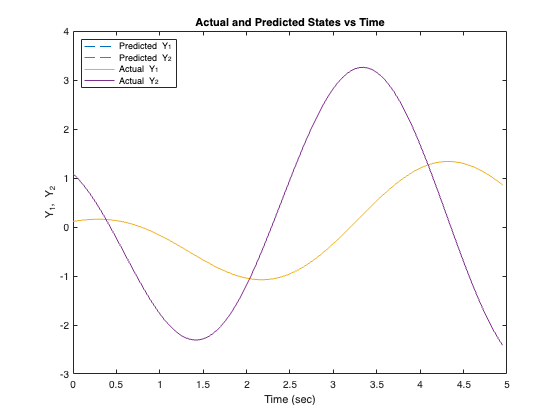


x_1 = F*x0 + G*udata(1,:)'; % get first x values
y_1 = [ x_1(1,1);x_1(2,1) - x_1(4,1)]; % y1 = q1; y2 = y2'-y4'

xdot = x_1;  %assign first xdot
ypred = y_1;  % assign first y prediction

for i=2:n
    xdot(:,i) = F*xdot(:,i-1) + G*udata(i,:)' ;
    ypred(:,i) = H*xdot(:,i);
end

f2=figure;
plot(tlist(1:n),ypred,"--",tlist(1:n),ydata')
title('Actual and Predicted States vs Time')
xlabel('Time (sec)')
ylabel('Y_1, Y_2')
legend({'Predicted Y_1', 'Predicted Y_2', 'Actual Y_1', 'Actual Y_2'},'Location','northwest')

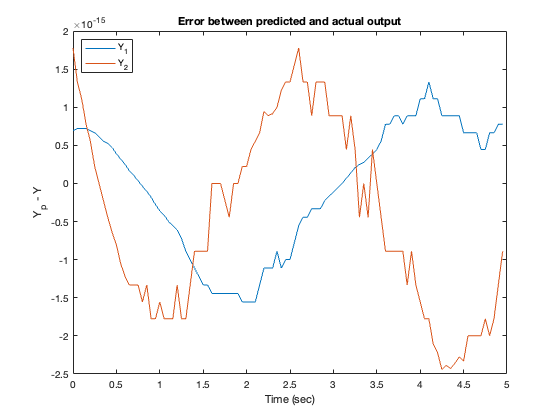


f3=figure;
p=plot(tlist(1:n),ypred-ydata');
title("Error between predicted and actual output");
ylabel('Y_p - Y');
xlabel('Time (sec)')
legend({'Y_1','Y_2'}, 'Location','northwest')

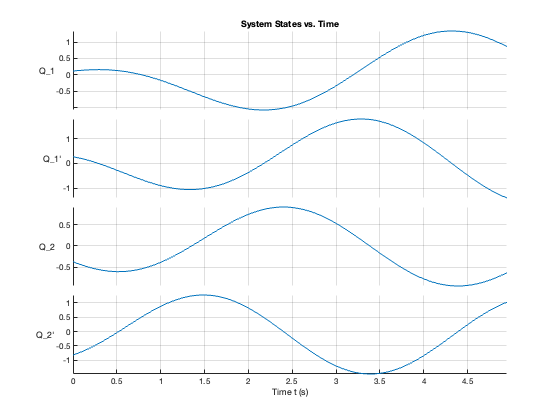


f1=figure;
s=stackedplot(tlist(1:100), xdot');
xlabel('Time t (s)');
s.DisplayLabels={'Q_1', 'Q_1''', 'Q_2', 'Q_2'''};
ax = findobj(s.NodeChildren, 'Type','Axes');
set([ax.YLabel],'Rotation',90,'HorizontalAlignment', 'Center', 'VerticalAlignment', 'Bottom')
title('System States vs. Time');
grid on;